# Channel Matched Filter Equalizer

% Uplink
% Achievable Rate V.S. Power
% Linear Formation and Rectangular Formation

## Global Parameter

clc
clearvars


M1 = 8;
M2 = 8;
M = M1 * M2;
K = 10;

taps = 4;

time = 100;
cyclic = 20;

use = 5;

points = 400;

dn = 0.5;

r = logspace(-2, 2, points);
e = mag2db(r) / 2;

alpha = 0.99;
eta = 500;
mu = 0;


## Correlation Patterns

for i = 1 : M
    for j = 1 : M
        dist(i, j) = abs(i - j) * dn;
    end
end

arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
arg = sqrt(arg);
bsl_1D = besseli(0, arg) ./ besseli(0, eta);
exp_1D = alpha .^ dist;
clear dist;

i = 1;
for c1 = 1 : M1
    for r1 = 1 : M2
        j = 1;
        for c2 = 1 : M1
            for r2 = 1 : M2
                dist(i, j) = (c2 - c1) ^ 2 + (r1 - r2) ^ 2;
                j = j + 1;
            end
        end
        i = i + 1;
    end
end

dist = sqrt(dist .* dn);
arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
arg = sqrt(arg);
bsl_2D = besseli(0, arg) ./ besseli(0, eta);
exp_2D = alpha .^ dist;
clear dist;


## Channel Power Delay Profile

u = (0 : K - 1) / 5;
for l = 1 : taps
    for k = 1 : K
        d1 = exp(-1 * u(k) * (0 : taps - 1));
        d(l, k) = exp(-1 * u(k) * (l - 1)) / (sum(d1));
    end
    D1 = diag(d(l, :));
    D(:, :, l) = D1;
end
%{

## Search Tree

for n = 1 : use
    S(:, :, n) = (sqrt(0.5)) * (randn(K, time) + 1i * randn(K, time));
    Z(:, :, n) = (sqrt(0.5)) * (randn(M, time + cyclic) + 1i * randn(M, time + cyclic));
    
    for l = 1: taps
        D1 = D(:, :, l) .^ (0.5);
        H1 = (sqrt(0.5)) * (randn(M, K) + 1i * randn(M, K));
        
        Hl_exp_1D(:, :, l, n) = conj((exp_1D ^ (0.5)) * H1) * D1;
        Hl_bsl_1D(:, :, l, n) = conj((bsl_1D ^ (0.5)) * H1) * D1;
        Hl_exp_2D(:, :, l, n) = conj((exp_2D ^ (0.5)) * H1) * D1;
        Hl_bsl_2D(:, :, l, n) = conj((bsl_2D ^ (0.5)) * H1) * D1;
        
        Ql_exp_1D(:, :, l, n) = Hl_exp_1D(:, :, l, n)';
        Ql_bsl_1D(:, :, l, n) = Hl_bsl_1D(:, :, l, n)';
        Ql_exp_2D(:, :, l, n) = Hl_exp_2D(:, :, l, n)';
        Ql_bsl_2D(:, :, l, n) = Hl_bsl_2D(:, :, l, n)';
    end
    [AQ1(n)] = Signal_Power(taps, Ql_exp_1D(:, :, :, n));
    [AQ2(n)] = Signal_Power(taps, Ql_bsl_1D(:, :, :, n));
    [AQ3(n)] = Signal_Power(taps, Ql_exp_2D(:, :, :, n));
    [AQ4(n)] = Signal_Power(taps, Ql_bsl_2D(:, :, :, n));
    
    % Composite Effect Matrix
    for l = 1 : taps
        E1(:, :, l, n) = (Ql_exp_1D(:, :, l, n)) * (Hl_exp_1D(:, :, l, n));
        E2(:, :, l, n) = (Ql_bsl_1D(:, :, l, n)) * (Hl_bsl_1D(:, :, l, n));
        E3(:, :, l, n) = (Ql_exp_2D(:, :, l, n)) * (Hl_exp_2D(:, :, l, n));
        E4(:, :, l, n) = (Ql_bsl_2D(:, :, l, n)) * (Hl_bsl_2D(:, :, l, n));
    end
end
a1 = 1 / mean(AQ1);
a2 = 1 / mean(AQ2);
a3 = 1 / mean(AQ3);
a4 = 1 / mean(AQ4);

% Desired Signal
for n = 1 : use
    for k = 1 : K
        for l = 1 : taps
            gk1(k, :, n, l) = E1(k, k, l ,n) * S(k, :, n);
            gk2(k, :, n, l) = E2(k, k, l ,n) * S(k, :, n);
            gk3(k, :, n, l) = E3(k, k, l ,n) * S(k, :, n);
            gk4(k, :, n, l) = E4(k, k, l ,n) * S(k, :, n);
        end
    end
end
g1 = sum(gk1, 4);
clear gk1;
g2 = sum(gk2, 4);
clear gk2;
g3 = sum(gk3, 4);
clear gk3;
g4 = sum(gk4, 4);
clear gk4;

% Transmitt Signal
X = S;
for j = 1 : cyclic
    X(:, time + j, :) = X(:, j, :); % Cyclic Prefix
end

% Channel Output Signal
for n = 1 : use
    for l = 1 : taps
        for j = 0 : time + cyclic -1
            rk1(:, j + 1, n, l) = (Hl_exp_1D(:, :, l, n)) * X(:, mod(j - l, time) + 1, n);
            rk2(:, j + 1, n, l) = (Hl_bsl_1D(:, :, l, n)) * X(:, mod(j - l, time) + 1, n);
            rk3(:, j + 1, n, l) = (Hl_exp_2D(:, :, l, n)) * X(:, mod(j - l, time) + 1, n);
            rk4(:, j + 1, n, l) = (Hl_bsl_2D(:, :, l, n)) * X(:, mod(j - l, time) + 1, n);
        end
    end
end
r1 = sum(rk1, 4);
clear rk1;
r2 = sum(rk2, 4);
clear rk2;
r3 = sum(rk3, 4);
clear rk3;
r4 = sum(rk4, 4);
clear rk4;

% Received Signal
for n = 1 : use
    for l = 1 : taps
        for j = 0 : time + cyclic - 1
            yk1(:, j + 1, n, l) = Ql_exp_1D(:, :, l, n) * r1(:, mod(j + l, time) + 1, n);
            yk2(:, j + 1, n, l) = Ql_bsl_1D(:, :, l, n) * r2(:, mod(j + l, time) + 1, n);
            yk3(:, j + 1, n, l) = Ql_exp_2D(:, :, l, n) * r3(:, mod(j + l, time) + 1, n);
            yk4(:, j + 1, n, l) = Ql_bsl_2D(:, :, l, n) * r4(:, mod(j + l, time) + 1, n);
        end
    end
end
y1 = sum(yk1, 4);
clear yk1 r1;
y2 = sum(yk2, 4);
clear yk2 r2;
y3 = sum(yk3, 4);
clear yk3 r3;
y4 = sum(yk4, 4);
clear yk4 r4;

% Effective Noise
z1 = y1(:, 1 : time, :) - g1;
z2 = y2(:, 1 : time, :) - g2;
z3 = y3(:, 1 : time, :) - g3;
z4 = y4(:, 1 : time, :) - g4;

for n = 1 : use
    for l = 1 : taps
        for j = 0 : time + cyclic - 1
            wgn1(:, n, j + 1, l) = a1 * Ql_exp_1D(:, :, l, n) * Z(:, mod(j + l, time) + 1, n);
            wgn2(:, n, j + 1, l) = a2 * Ql_bsl_1D(:, :, l, n) * Z(:, mod(j + l, time) + 1, n);
            wgn3(:, n, j + 1, l) = a3 * Ql_exp_2D(:, :, l, n) * Z(:, mod(j + l, time) + 1, n);
            wgn4(:, n, j + 1, l) = a4 * Ql_bsl_2D(:, :, l, n) * Z(:, mod(j + l, time) + 1, n);
        end
    end
end
noise1 = mean(var(sum(wgn1, 4), 0, 3), 2);
clear wgn1;
noise2 = mean(var(sum(wgn2, 4), 0, 3), 2);
clear wgn2;
noise3 = mean(var(sum(wgn3, 4), 0, 3), 2);
clear wgn3;
noise4 = mean(var(sum(wgn4, 4), 0, 3), 2);
clear wgn4;

F1 = sum(mean(E1, 4), 3);
F2 = sum(mean(E2, 4), 3);
F3 = sum(mean(E3, 4), 3);
F4 = sum(mean(E4, 4), 3);

for n = 1 : use
    for k = 1 : K
        Sn1 = abs(a1 * (F1(k, k))) ^ 2 * r;
        Sn2 = abs(a2 * (F2(k, k))) ^ 2 * r;
        Sn3 = abs(a3 * (F3(k, k))) ^ 2 * r;
        Sn4 = abs(a4 * (F4(k, k))) ^ 2 * r;
        
        Vn1 = var(a1 * z1(k, :, n), 0, 2) * r + noise1(k);
        Vn2 = var(a2 * z2(k, :, n), 0, 2) * r + noise2(k);
        Vn3 = var(a3 * z3(k, :, n), 0, 2) * r + noise3(k);
        Vn4 = var(a4 * z4(k, :, n), 0, 2) * r + noise4(k);
        
        SNR1 = Sn1 ./ Vn1;
        SNR2 = Sn2 ./ Vn2;
        SNR3 = Sn3 ./ Vn3;
        SNR4 = Sn4 ./ Vn4;
        
        Rk1(:, k, n) = log2(1 + SNR1);
        Rk2(:, k, n) = log2(1 + SNR2);
        Rk3(:, k, n) = log2(1 + SNR3);
        Rk4(:, k, n) = log2(1 + SNR4);
    end
end

R1 = 0.5 * mean(sum(Rk1, 2), 3);
clear Sn1 Vn1 SNR1 Rk1;
R2 = 0.5 * mean(sum(Rk2, 2), 3);
clear Sn2 Vn2 SNR2 Rk2;
R3 = 0.5 * mean(sum(Rk3, 2), 3);
clear Sn3 Vn3 SNR3 Rk3;
R4 = 0.5 * mean(sum(Rk4, 2), 3);
clear Sn4 Vn4 SNR4 Rk4;
%}

## Mathematical Results

for l = 1 : taps
    for k = 1 : K
        V1(l, k) = d(l, k) ^ 2;
        V2(l, k) = d(l, k);
    end
end
first = sum(V1, 1);
second = sum(V2, 1);

for k = 1 : K
    Vg1 = (r ./ (M * K)) * (trace(exp_1D * exp_1D') * (first(k)) + (trace(exp_1D) ^ 2) * (second(k)) .^ 2);
    Vn1 = r * (trace(exp_1D * exp_1D') ./ M) * (1 - V2(k) / K) + 1 / K;
    R1_k(:, k) = log2(1 + Vg1 ./ Vn1);
    
    Vg2 = (r ./ (M * K)) * (trace(bsl_1D * bsl_1D') * (first(k)) + (trace(bsl_1D) ^ 2) * (second(k)) .^ 2);
    Vn2 = r * (trace(bsl_1D * bsl_1D') ./ M) * (1 - V2(k) / K) + 1 / K;
    R2_k(:, k) = log2(1 + Vg2 ./ Vn2);
    
    Vg3 = (r ./ (M * K)) * (trace(exp_2D * exp_2D') * (first(k)) + (trace(exp_2D) ^ 2) * (second(k)) .^ 2);
    Vn3 = r * (trace(exp_2D * exp_2D') ./ M) * (1 - V2(k) / K) + 1 / K;
    R3_k(:, k) = log2(1 + Vg3 ./ Vn3);
    
    Vg4 = (r ./ (M * K)) * (trace(bsl_2D * bsl_2D') * (first(k)) + (trace(bsl_2D) ^ 2) * (second(k)) .^ 2);
    Vn4 = r * (trace(bsl_2D * bsl_2D') ./ M) * (1 - V2(k) / K) + 1 / K;
    R4_k(:, k) = log2(1 + Vg4 ./ Vn4);
    
end
R1 = 0.5 * sum(R1_k, 2);
R2 = 0.5 * sum(R2_k, 2);
R3 = 0.5 * sum(R3_k, 2);
R4 = 0.5 * sum(R4_k, 2);

factor = (time) / (time + cyclic);

R1 = factor * R1;
R2 = factor * R2;
R3 = factor * R3;
R4 = factor * R4;


## Plots

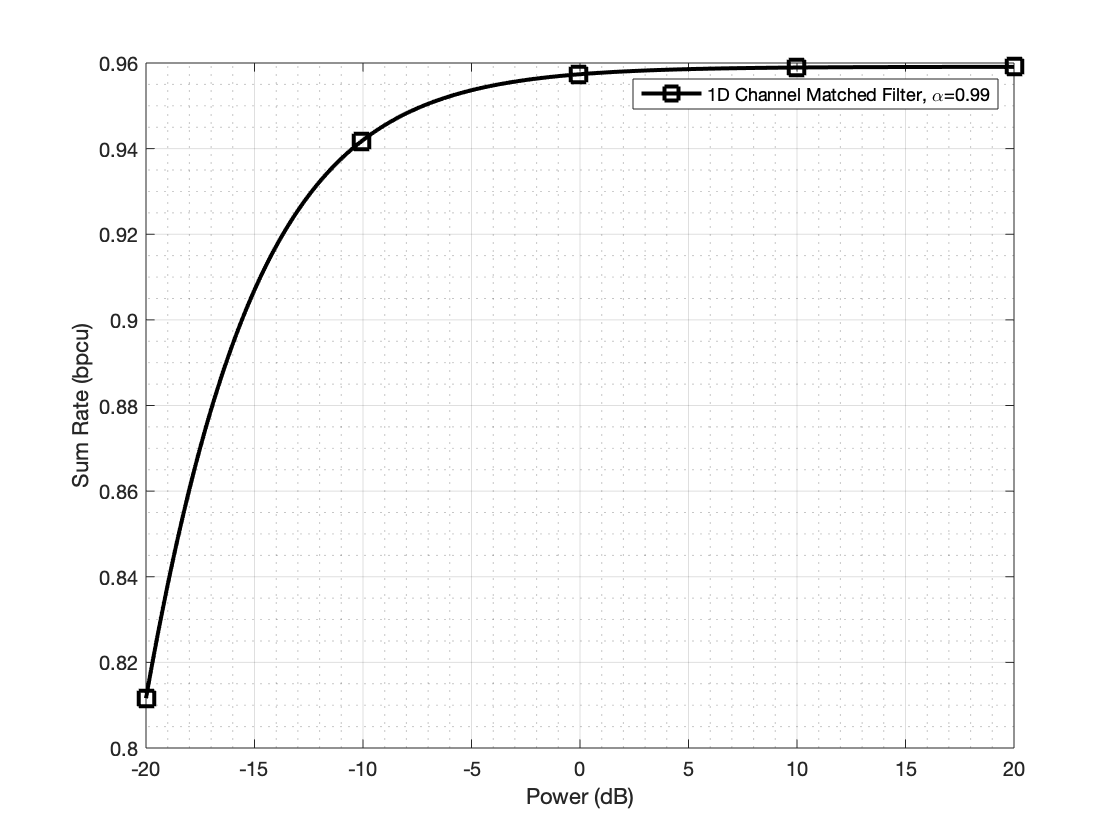

index = [1, 100, 200, 300, 400];

angel = strcat('\pi/', num2str(pi / mu));
if (mu == 0)
    angel = num2str(0);
end

name_a = '1D Channel Matched Filter';
name_b = '2D Channel Matched Filter';

name1 = strcat(name_a, ', \alpha=', num2str(alpha));
% name2 = strcat(name_a, ', \eta=', num2str(eta), ', \mu=', angel);
name2 = strcat(name_a, ', \eta=', num2str(eta));
name3 = strcat(name_b, ', \alpha=', num2str(alpha));
% name4 = strcat(name_b, ', \eta=', num2str(eta), ', \mu=', angel);
name4 = strcat(name_b, ', \eta=', num2str(eta));

x_label = 'Power (dB)';
y_label = 'Sum Rate (bpcu)';

style = '-ks';

figure;
plot(e, R1, style, 'DisplayName', name1, 'MarkerIndices', index, 'MarkerSize', 10);

xlabel(x_label, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

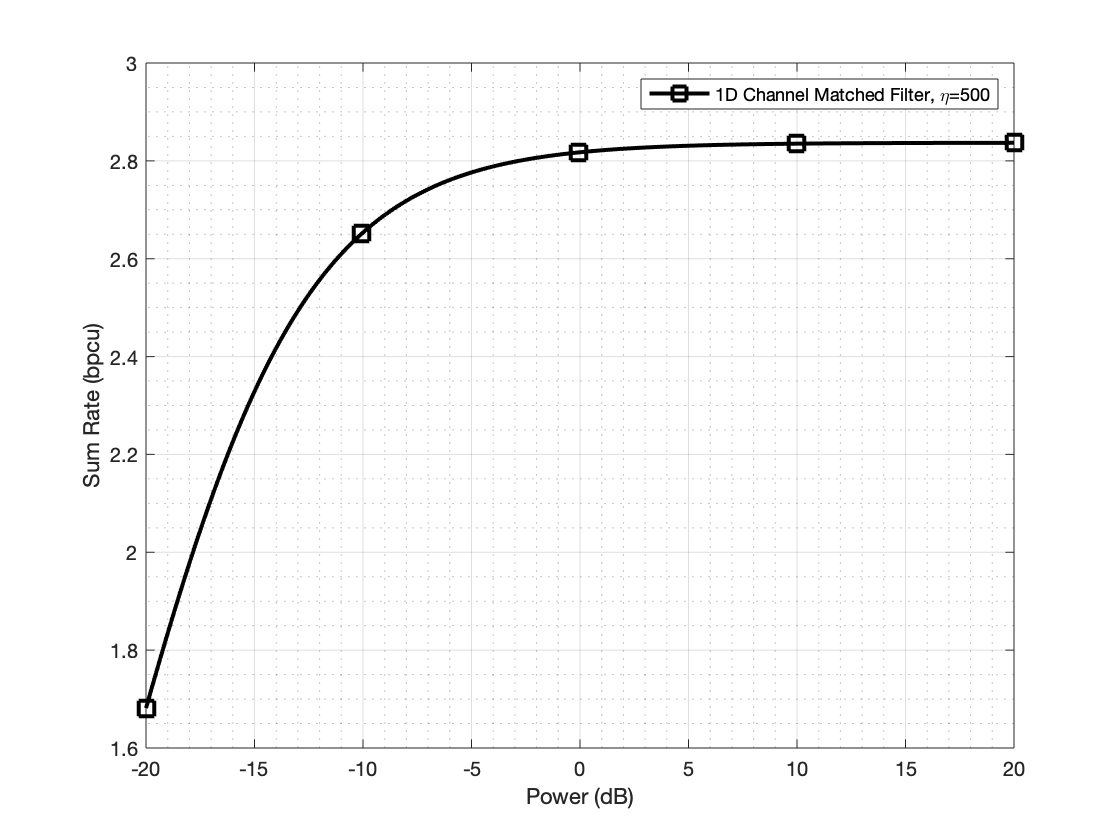



figure;
plot(e, R2, style, 'DisplayName', name2, 'MarkerIndices', index, 'MarkerSize', 10);

xlabel(x_label, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

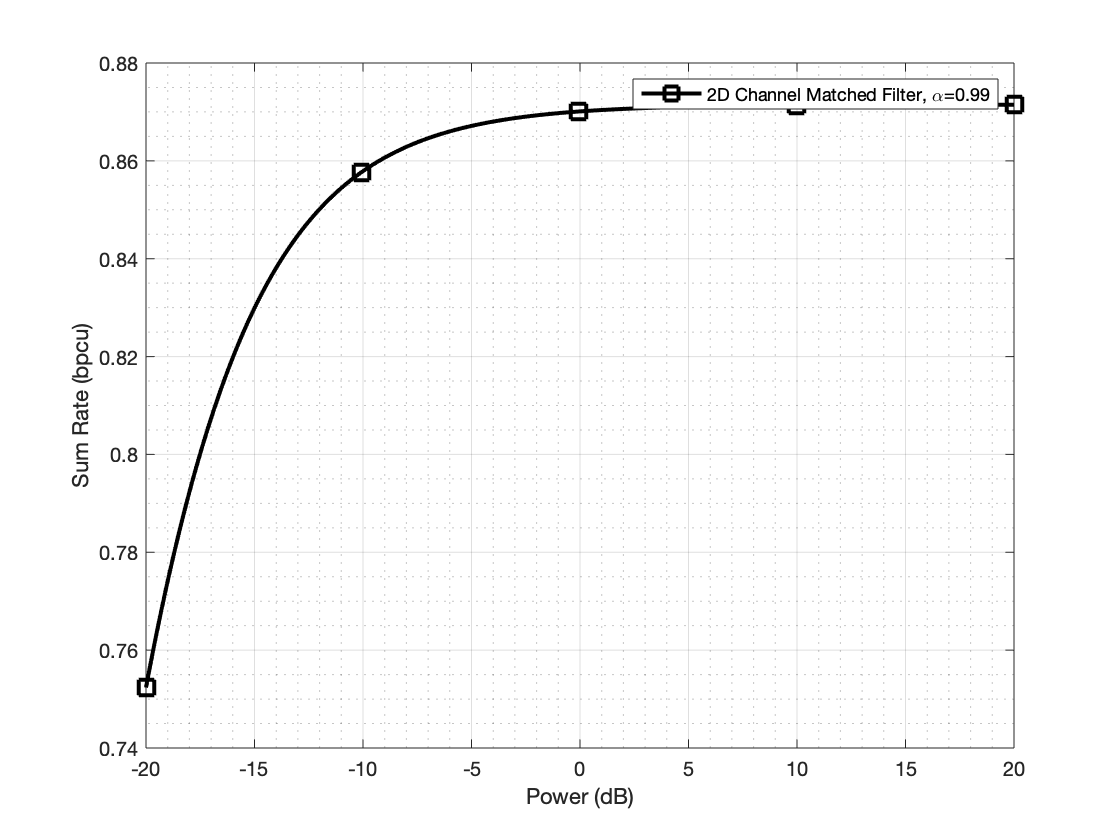


figure;
plot(e, R3, style, 'DisplayName', name3, 'MarkerIndices', index, 'MarkerSize', 10);

xlabel(x_label, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

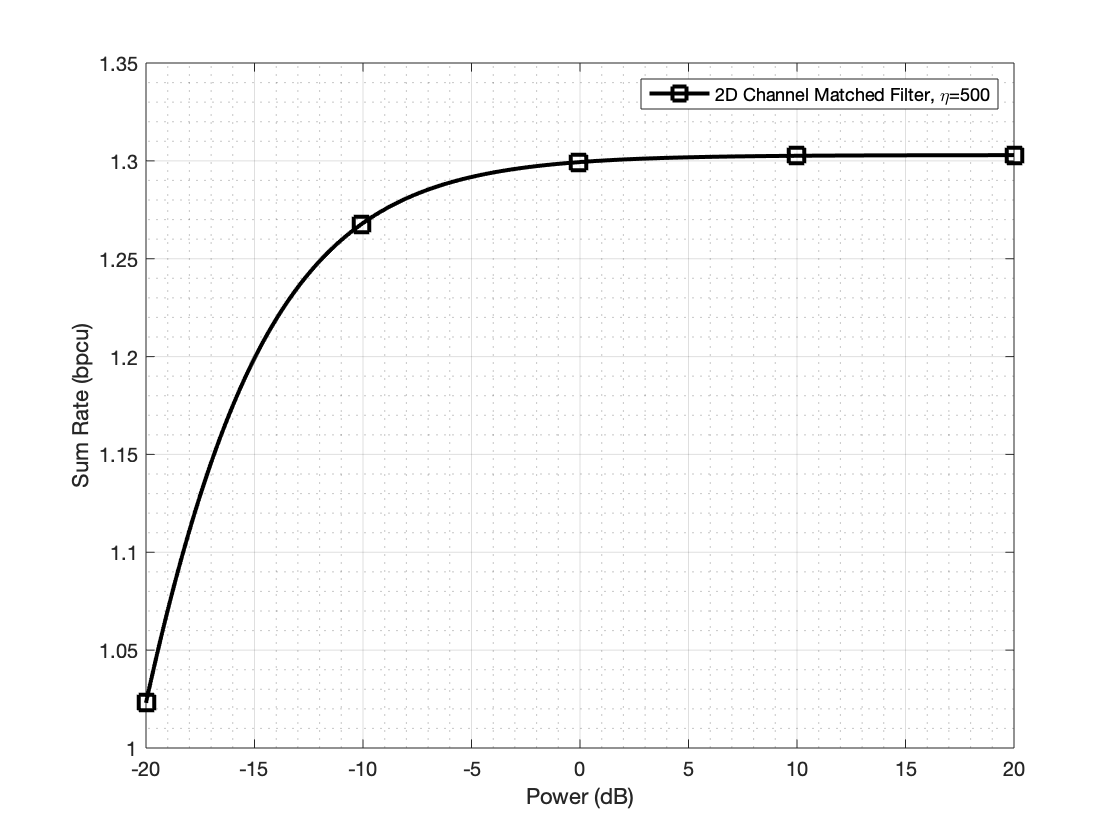



figure;
plot(e, R4, style, 'DisplayName', name4, 'MarkerIndices', index, 'MarkerSize', 10);

xlabel(x_label, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;